Question 32

clc;
clear;
close all;


s=tf('s');
K=1

K = 1

F=K/((s+1)*(s+3)*(s+6)^2);
sys=tf(F)

sys =
 
                   1
  -----------------------------------
  s^4 + 16 s^3 + 87 s^2 + 180 s + 108
 
Continuous-time transfer function.




stepinfo(sys)

ans = struct with fields:
         RiseTime: 2.4769
    TransientTime: 4.6821
     SettlingTime: 4.6821
      SettlingMin: 0.0083
      SettlingMax: 0.0093
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0093
         PeakTime: 9.5020


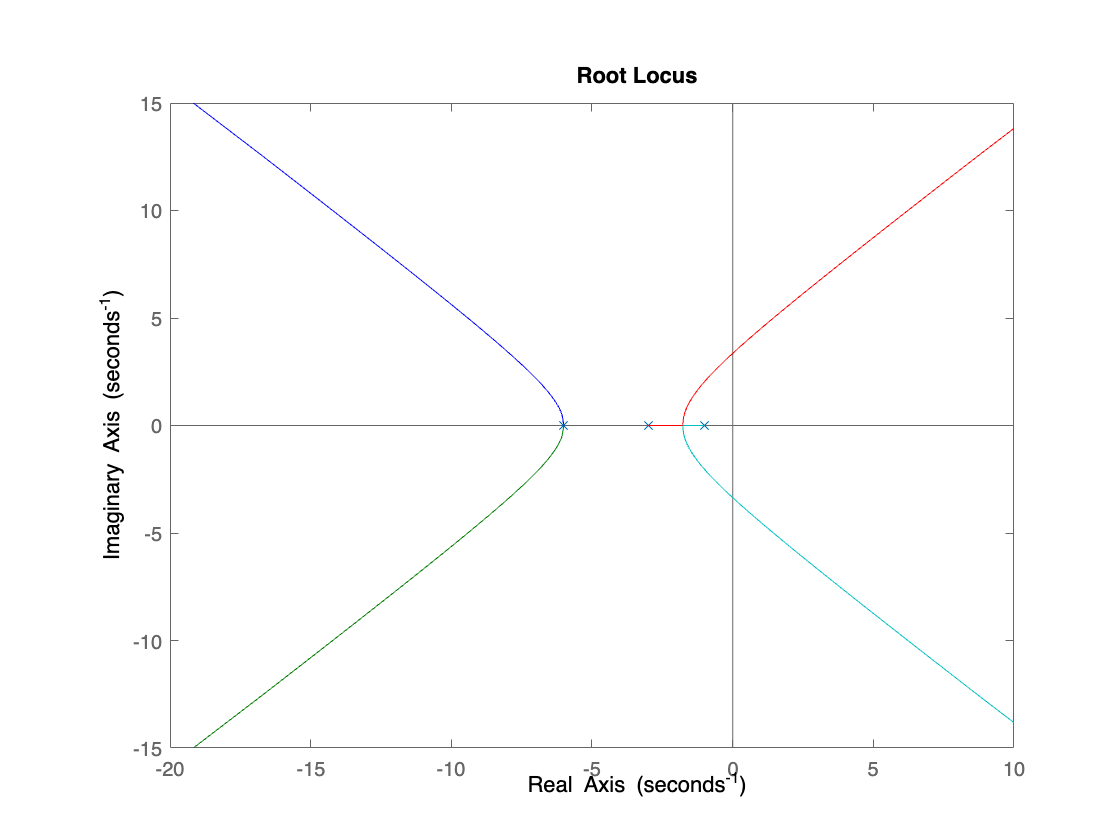


%B
rlocus(sys)

%gain = 16.9

Question 33

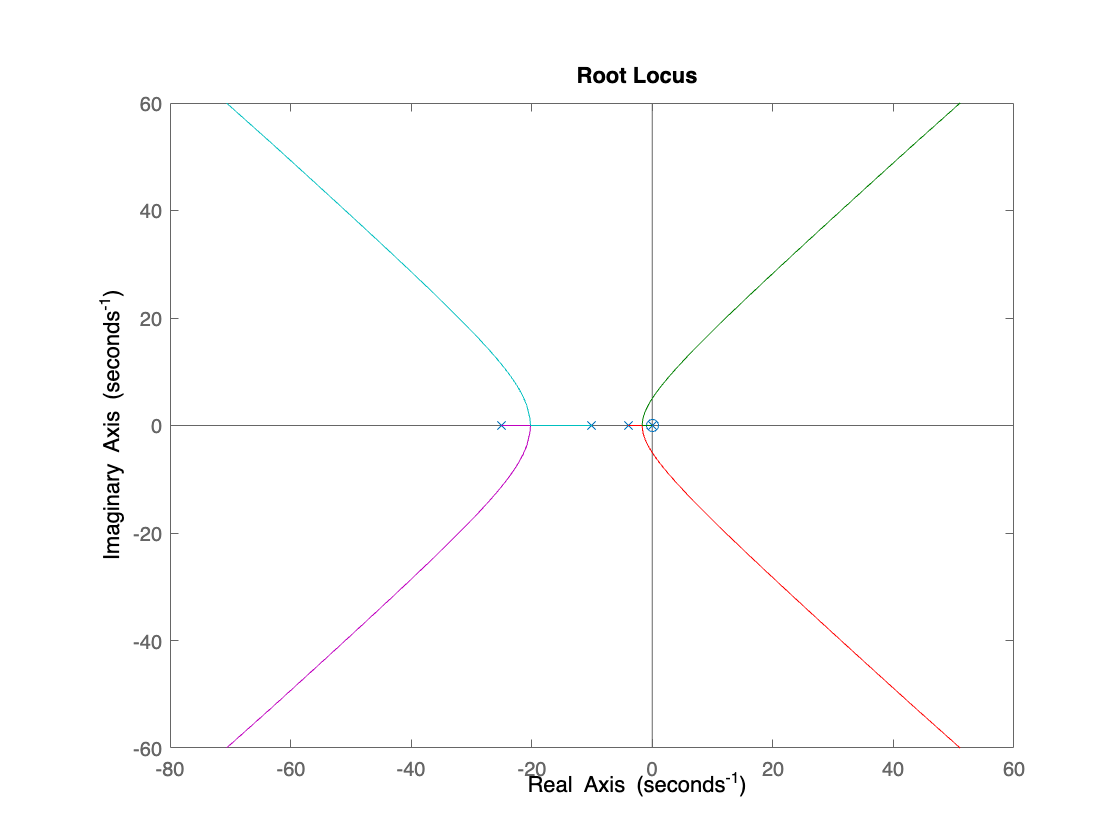

s=tf('s');

F=(s+0.02)/(s^2*(s+4)*(s+10)*(s+25));

rlocus(F) %gain 2200

k=2200

k = 2200

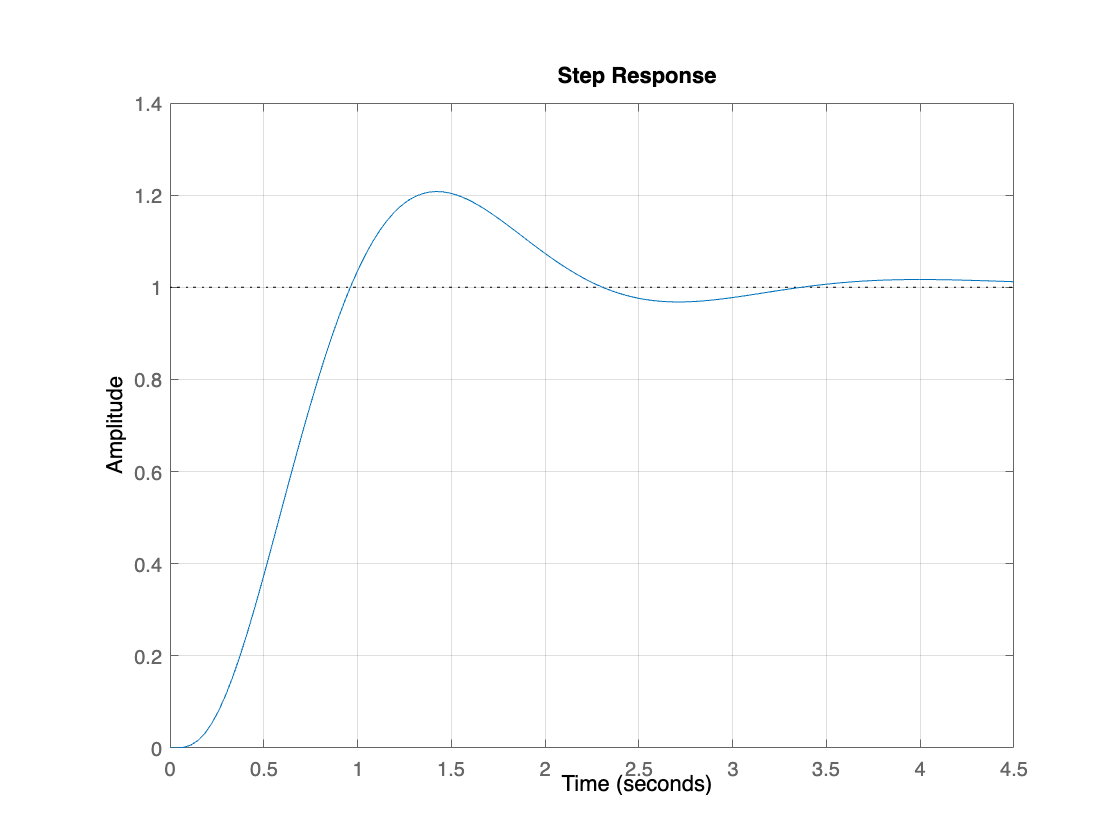

step(feedback(F*k,1));grid